# Unidad 6 - TP08b

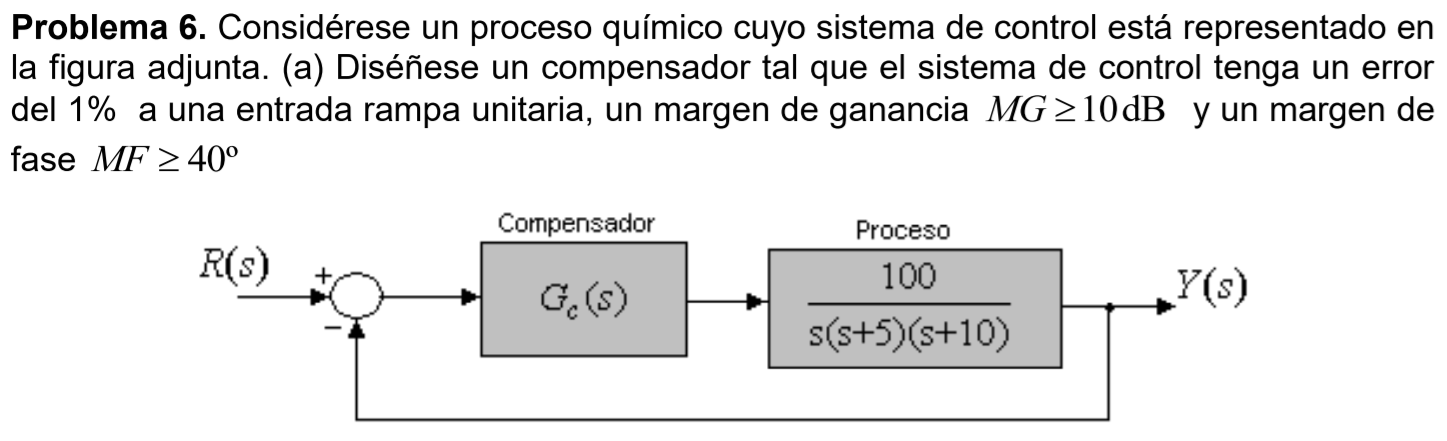

## Requisitos

- $e_{\textrm{ss}} =1%$, es decir $k_v =100\;\frac{1}{s}$

- 
$$\textrm{MG}\ge 10\;\textrm{dB}$$


- 
$$\textrm{MF}=40°$$


## Analizamos la planta

Sin proponer ninguna red para compensar, analizemos que sucede con el $e_{\textrm{ss}}$, sabiendo que la constante *k* va a estar incluida en nuestro análisis de MG y MF.


$$G_C \left(s\right)=k\;\frac{\textrm{sT}+1}{\textrm{sT}\alpha +1}$$


Donde,


$$k=\;k_c \;\alpha$$



$$0<\alpha$$



$$k_v =\lim_{s\to 0} \;s\;k\frac{\textrm{sT}+1}{\textrm{sT}\alpha +1}\;\frac{100}{s\left(s+5\right)\left(s+10\right)}$$



$$k_v =k\;\frac{100}{50}$$



$$\frac{k_v }{2}=k$$



$$k=50$$


Ahora si, veamos que sucede con MG y MF,

clear;
s = tf('s');
G = 100/(s*(s+5)*(s+10));
H = 1;
k = 50;
margin(k*G*H);
grid on;

## Diseño

Como era de esperar, nuestro sistema esta muy exigido en cuanto a MG y MF, por lo que podríamos encarar directamente con una red de **adelanto-retraso**. Pero veamos que sucede si intentamos compensar al sistema diseñando una red de **atraso de fase.**

$G_c \left(s\right)=k\;\frac{\left(\textrm{sT}+1\right)}{\left(\textrm{sT}\beta +1\right)}$;

Donde,


$${k\;=\;k}_c \;\beta$$



$$\beta >1$$


Ya tenemos el valor de k de nuestro analisis previo. Con este dato podemos entonces obtener la frecuencia a la cual nuestro sistema presenta el MF solicitado, adicionando 12° para tener un margen de diseño

bode(k*G*H);
grid on;

Quedando entonces nuestra $w_c =2\;\frac{\textrm{rad}}{s}$, diseñando entonces y del mismo análisis extraemos del gráfico de magnitud que $\left|G\left(w_c \right)\right|=33\;\textrm{dB}$. Esta será la atenuación que debe agregar nuestra red para que se cumpla la condición del MF. Por lo tanto,


$$\textrm{Att}=-20\;\log_{10} \left(\frac{1}{\beta }\right)$$



$$\beta ={10}^{\frac{\textrm{Att}}{20}}$$



$$k_c =\frac{k}{\beta }$$



$$\left|z\right|\le \frac{w_c }{10}$$



$$T=\frac{1}{\left|z\right|}$$



$$\left|p\right|=\frac{1}{T\beta }$$


wc = 2;
beta = 10^(33/20);
kc = k/beta;
z = wc/10
T = 1/z
p = 1/(T*beta)

## Verificación

Gc = (kc*beta) * (s*T+1)/(s*T*beta+1);
M = feedback(G, H);
Mc = feedback(Gc*G, H)

% Bode del compensador
bode(Gc);
grid on;

% Margenes de fase y ganancia.
margin(Gc*G*H);
grid on;

% Comparativa de los bode.
bode(G*H, Gc*G*H);
grid on;
legend("Sin compensar", "Compensado");

% Respuesta al escalón
step(M, Mc);
grid on;
legend("Sin compensar", "Compensado");

% Respuesta a la rampa
[y,t]=step(M*tf(1,[1 0]), 10);
[yc,tc]=step(Mc*tf(1,[1 0]), 10);
plot(t,t,'k', t,y,'r', tc,yc,'b');
legend("Rampa unitaria", "Sin compensar", "Compensado");
grid on;

## Rediseño

Propongamos ahora si una **red de adelanto-retraso de fase.** Y comparemos los resultados.


$$G_c \left(s\right)=k_c \;\frac{{s\;T}_1 +1}{s\;\frac{T_1 }{\beta }+1}\;\frac{{s\;T}_2 +1}{s\;T_2 \;\beta +1}$$



$$\beta >1$$


Manteniendo $k=50$, comenzamos diseñando nuestra red desde la red de retraso, seleccionando del bode de nuestro sistema la frecuencia ($w_{\textrm{c2}}$) a la cual tenemos -180° de fase y la atenuación necesaria para lograr que ese sea nuestro MF.

bode(k*G*H);
grid on;

Obteniendo entonces $w_{\textrm{c2}} =7\;\frac{\textrm{rad}}{s}$ y $\left|G\left(w_{\textrm{c2}} \right)\right|=16\ldotp 6\;\textrm{dB}$, por lo tanto ${\left|\mathrm{Att}\right|}_{\mathrm{dB}} =-16\ldotp 6\;\mathrm{dB}$.

wc_ar = 7
Att_ar_dB = -16.6

Por diseño fijaremos también nuestor $\phi_m =60°$ (${\textrm{MF}}_{\textrm{req}} +12°$).

Recordando que, 


$$\sin \left(\phi_m \right)=\frac{1-\alpha }{1+\alpha }$$



$$\sin \left(\phi_m \right)=\frac{1-\frac{1}{\beta }}{1+\frac{1}{\beta }}$$



$$\beta =\frac{1+\sin \left(\phi_m \right)}{1-\sin \left(\phi_m \right)}$$


phm = 40 + 12;
phm_rad = phm / 180 * pi;
beta_ar = (1+sin(phm_rad)) / (1-sin(phm_rad))

Quedando entonces nuestro diseño como,


$$z_r =\frac{w_c }{10}$$



$$p_r =\frac{z_r }{\beta }$$



$$z_a =w_c \;{10}^{\frac{{\left(\frac{1}{\beta }\right)}_{\textrm{dB}} -{\left|\textrm{Att}\right|}_{\textrm{dB}} }{20}}$$



$$p_a =z_a \;\beta$$


zr = wc_ar / 10
pr = zr / beta_ar
za = wc_ar * 10 ^ ( ( (20*log10(1/beta_ar)) - Att_ar_dB) / 20 )
pa = za * beta_ar
T1 = 1/(beta_ar*pa)
T2 = 1/(beta_ar*pr)

## Verificación red de adelanto-retraso

Gc_ar = (k) * ((s+za)/(s+pa)) * ((s+zr)/(s+pr))
Mc_ar = feedback(Gc_ar*G, H)

% Bode del compensador
bode(Gc_ar);
grid on;

% Margenes de fase y ganancia.
margin(Gc_ar*G*H);
grid on;

% Comparativa de los bode.
bode(G*H, Gc_ar*G*H);
grid on;
legend("Sin compensar", "Compensado");

% Respuesta al escalón
step(M, Mc_ar);
grid on;
legend("Sin compensar", "Compensado");

% Respuesta a la rampa
[y,t]=step(M*tf(1,[1 0]), 10);
[yc_ar,tc_ar]=step(Mc_ar*tf(1,[1 0]), 10);
plot(t,t,'k', t,y,'r', tc_ar,yc_ar,'b');
legend("Rampa unitaria", "Sin compensar", "Compensado");
grid on;